close("all"); clear; clc;

A = [
    -1,-4;
    4,-1
    ];

B = [
    1;
    1
    ];

C = eye(2);

D = 0;

sys = ss(A,B,C,D);
ts = 0.02;
sysd = c2d(sys,ts);

X = zonotope2d(0.1.*eye(2),[1;0]);

umax = 0.05;
umin = -0.05;
U = zonotope2d([sysd.B*umin,sysd.B*umax]);

R = {X};
V = U;
S = zonotope2d(zeros(2,1));

for k = 1:100
    X = sysd.A*X;
    S = S + box(V);
    V = sysd.A*V;
    R{k} = box(X) + S;
end
R = [R{:}];

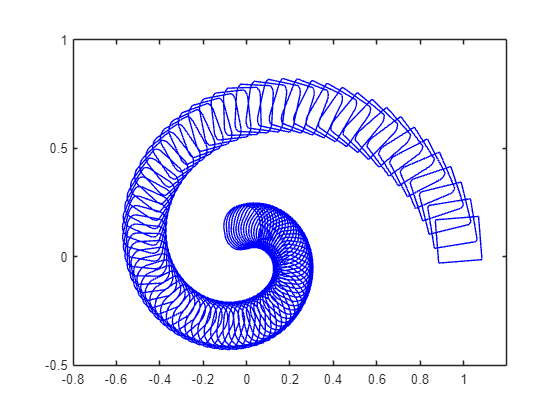

fig = figure();
axe = axes(fig);
arrayfun(@plot,R);
axis(axe,"equal");
box(axe,"on");
xlim([-0.8,1.2]);
ylim([-0.5,1]);